# **Đọc dữ liệu và vẽ đồ thị**

## 1. Tải dữ liệu

Truy cập website: [http://www.energyonline.com](http://www.energyonline.com) và chọn trong tab NYISO -> Hourly Actual Load:

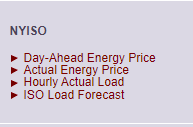

Hoặc lựa vào link sau: [http://www.energyonline.com/Data/GenericData.aspx?DataId=13&NYISO___Hourly_Actual_Load](http://www.energyonline.com/Data/GenericData.aspx?DataId=13&NYISO___Hourly_Actual_Load)

Lựa chọn **Start Date** và **End Date: 31/5/2023 **đến** 30/6/2023**

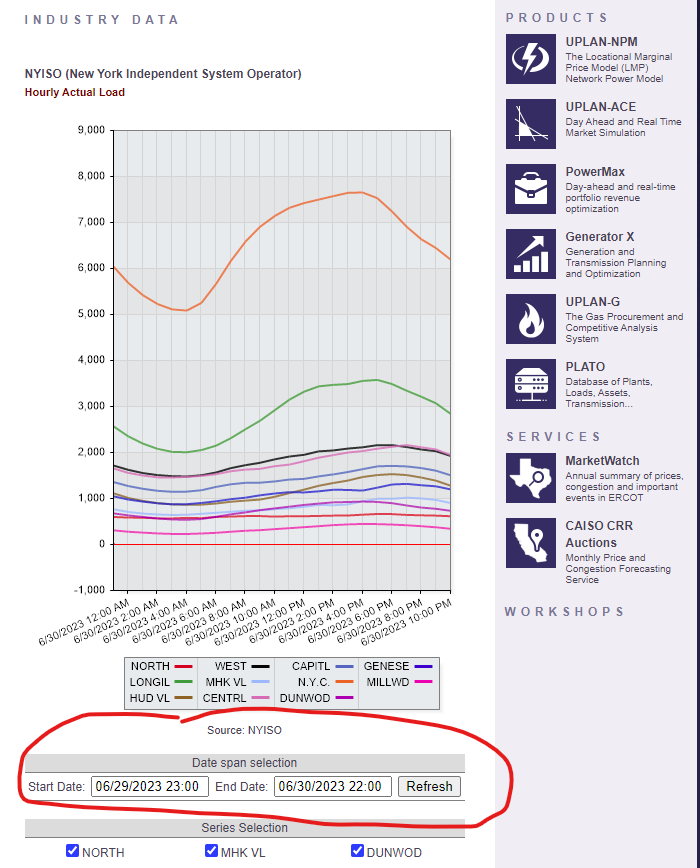

-> Chọn **Refresh** và **Export Data To Excel**

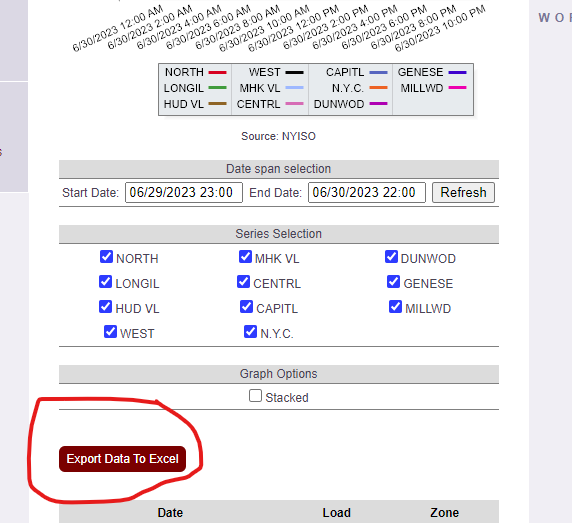

Sau khi tải dữ liệu sử dụng điện của thành phố New York trong tháng 6/2023, upload lên thư mục  **Matlab online** của các bạn (có thể thay đổi tên file để dễ quản lý). Định dạng file dữ liệu khi tải về là ***.csv**:

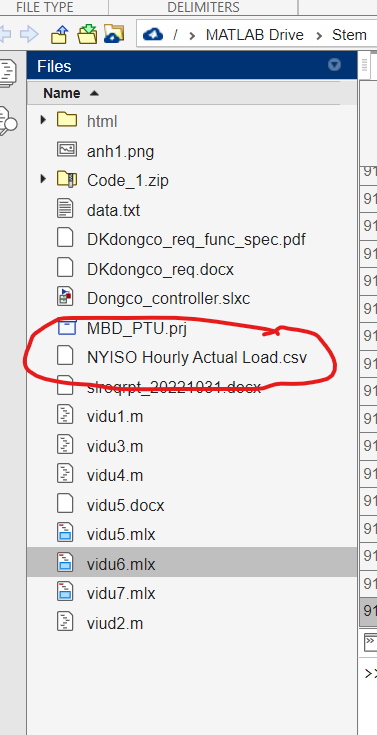

## 2. Đọc dữ liệu trong Matlab

Lựa chọn **import data**  file vừa upload lên để chương trình tự động đọc file .csv vào môi trường Matlab. 

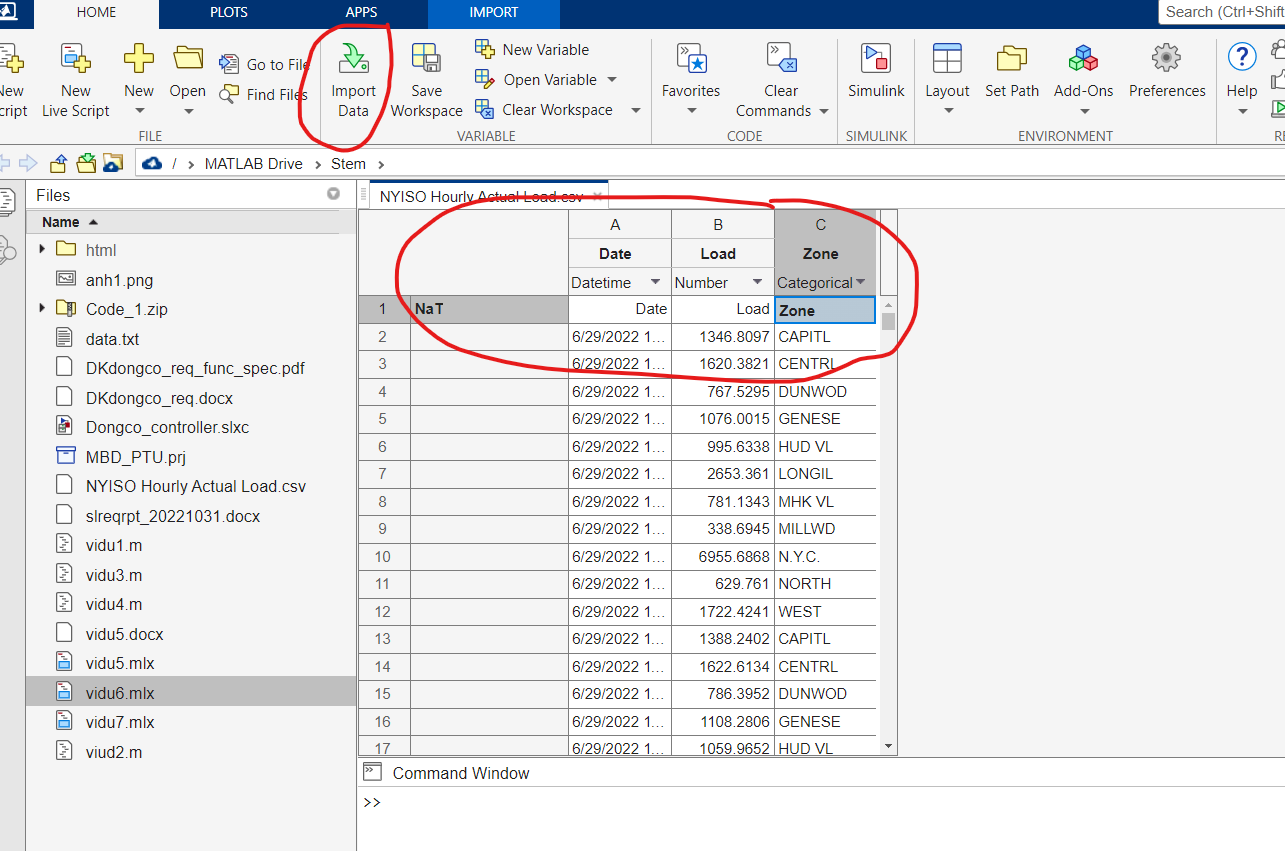

Trong tab Import Chọn 3 cột A,B, C đặt tên biến là **Data_Month_Electricity** và chọn kiểu dữ liệu là **String** **Array**, sau đó click **Import** **Selection**, lúc này biến **Data_Month_Electricity** xuất hiện trong **workspace**

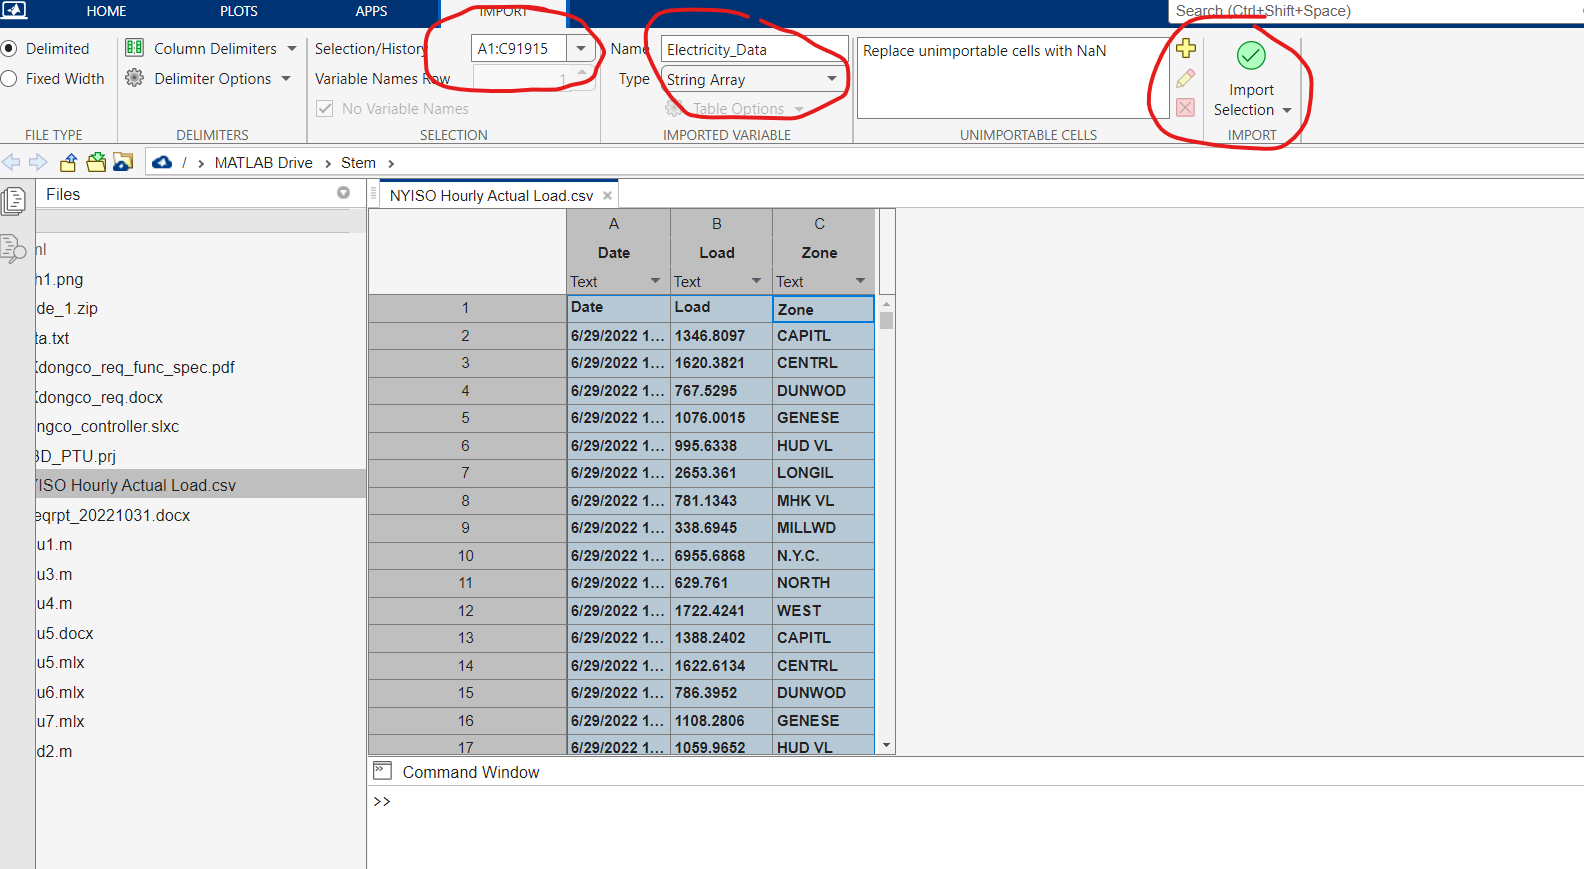

## 3. Bài tập

### 3.1. Đọc dữ liệu và vẽ đồ thị

Đọc dữ liệu tải sử dụng điện của thành phố NY  từ biến **Data_Month_Electricity **vào biến **Load_data**

% 
Load_data = DME(:,2)

Load_data = 7899×1 string array
    "Load"
    "1680.5474"
    "2135.9908"
    "652.1295"
    "1373.5979"
    "1221.7872"
    "2504.1725"
    "973.3943"
    "300.5015"
    "5546.2883"
    "670.1595"
    "2131.4245"
    "1604.3749"
    "2046.4299"
    "633.1876"
    "1311.8195"
    "1160.0509"
    "2392.5683"
    "939.3373"
    "290.9565"
    "5391.3798"
    "653.7888"
    "2054.0833"
    "1463.1595"
    "1884.5785"
    "583.1776"
    "1191.1732"
    "1047.8755"
    "2184.763"
    "843.3833"


Dữ liệu lưu trong **Load_data** là dữ liệu kiểu string. Biến dữ liệu này thành dữ liệu số để phân tích.

`Gới ý: Sử dụng hàm  str2double()`

%
Load_data_numeric = str2double(Load_data)

Load_data_numeric = 1.0e+03 *

       NaN
    1.6805
    2.1360
    0.6521
    1.3736
    1.2218
    2.5042
    0.9734
    0.3005
    5.5463


Trong dữ liệu sử dụng điện của thành phố NY có 10 vùng: NORTH, MHK VL, DUNWOD, LONGIL, CENTRL, GENESE, HUD VL, CAPITL, MILLWD, WESTN.Y.C. Đọc dữ liệu sử dụng điện của vùng CAPITL trong tháng 6/2023.

%
Load_data_CAPITL = str2double(DME((DME(:,3)=="CAPITL"),2))

Load_data_CAPITL = 1.0e+03 *

    1.6805
    1.6044
    1.4632
    1.3260
    1.2416
    1.1813
    1.1417
    1.1234
    1.1224
    1.1529


Vẽ biểu đồ dữ lệu sử dụng điện của vùng CAPITL này

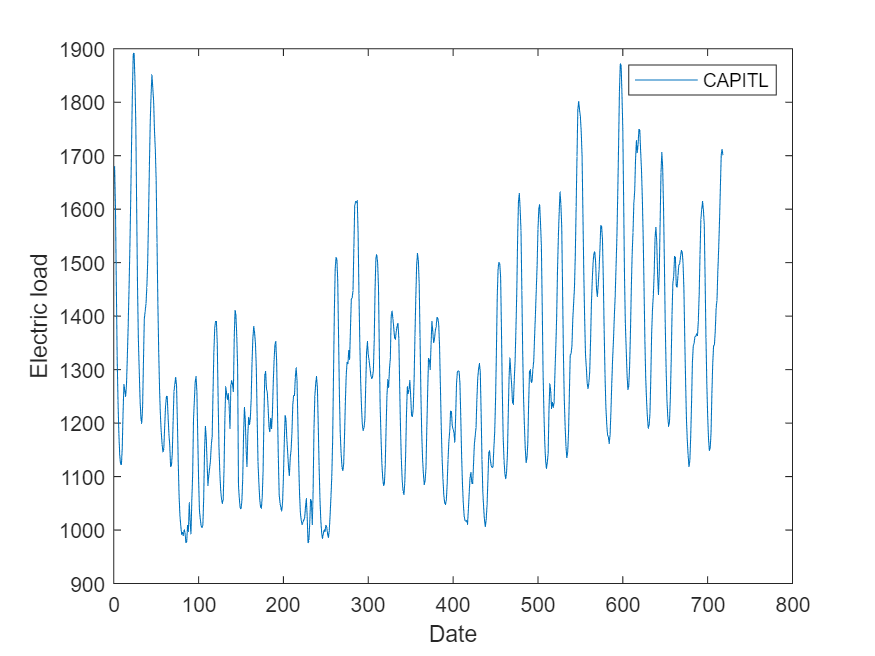

plot(Load_data_CAPITL)
legend("CAPITL")
xlabel("Date")
ylabel("Electric load")

So sánh đồ thị dữ liệu sử dụng điện của vùng CAPITL từ đồ thị Matlab với với dữ liệu của website.

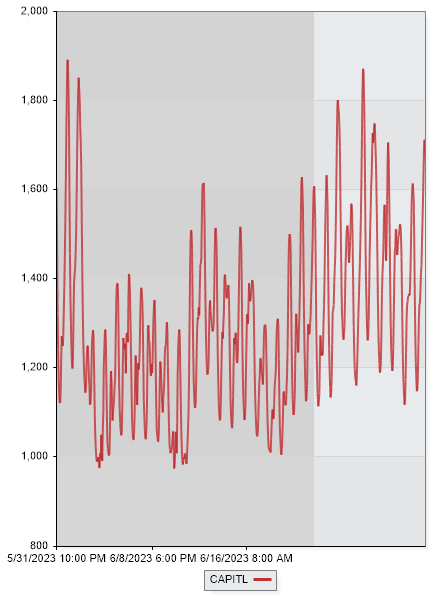

### 3.2. Phân tích dữ liệu

Tính tổng tải tiêu thụ điện của vùng CAPITL trong vòng 1 tháng và tính trung bình tải tiêu thu điện trong 1h vùng CAPITL

sum_CAPITL = sum(Load_data_CAPITL)

sum_CAPITL = 9.3229e+05

% Sau khi tính tải tiêu thụ điện trung bình có thể so sánh với kết quả
% mean(Load_data_Capitl). Hàm mean() là hàm xây dựng sẵn trong Matlab
% (được gọi là built-in function)
mean_CAPITL = mean(Load_data_CAPITL)

mean_CAPITL = 1.2984e+03

Tương tự tính dữ liệu sử dụng điện của vùng CENTRL, DUNWOD, GENESE, HUD VL, LONGIL, MHK VL, MILLWD,  N.Y.C., NORTH, WEST trong tháng 6/2023

% 
Load_data_CENTRL = str2double(DME((DME(:,3)=="CENTRL"),2))

Load_data_CENTRL = 1.0e+03 *

    2.1360
    2.0464
    1.8846
    1.7224
    1.6096
    1.5417
    1.4923
    1.4683
    1.4797
    1.5298


sum_CENTRL = sum(Load_data_CENTRL)

sum_CENTRL = 1.1591e+06

mean_CENTRL = mean(Load_data_CENTRL)

mean_CENTRL = 1.6143e+03


Load_data_DUNWOD = str2double(DME(DME(:,3)=="DUNWOD",2))

Load_data_DUNWOD =   652.1295
  633.1876
  583.1776
  527.9569
  493.5670
  474.5988
  453.2399
  439.6736
  437.4854
  452.3295


sum_DUNWOD = sum(Load_data_DUNWOD)

sum_DUNWOD = 4.4209e+05

mean_DUNWOD = mean(Load_data_DUNWOD)

mean_DUNWOD = 615.7219


Load_data_GENESE = str2double(DME(find(DME(:,3)=="GENESE"),2))

Load_data_GENESE = 1.0e+03 *

    1.3736
    1.3118
    1.1912
    1.0838
    1.0132
    0.9689
    0.9263
    0.9041
    0.9066
    0.9404


sum_GENESE = sum(Load_data_GENESE)

sum_GENESE = 7.2418e+05

mean_GENESE = mean(Load_data_GENESE)

mean_GENESE = 1.0086e+03


Load_data_HUDVL = str2double(DME(find(DME(:,3)=="HUD VL"),2))

Load_data_HUDVL = 1.0e+03 *

    1.2218
    1.1601
    1.0479
    0.9492
    0.8814
    0.8311
    0.8008
    0.7859
    0.7833
    0.8034


sum_HUDVL = sum(Load_data_HUDVL)

sum_HUDVL = 7.2197e+05

mean_HUDVL = mean(Load_data_HUDVL)

mean_HUDVL = 1.0055e+03


Load_data_LONGIL = str2double(DME(find(DME(:,3)=="LONGIL"),2))

Load_data_LONGIL = 1.0e+03 *

    2.5042
    2.3926
    2.1848
    1.9706
    1.8081
    1.7085
    1.6511
    1.6220
    1.6398
    1.7071


sum_LONGIL = sum(Load_data_LONGIL)

sum_LONGIL = 1.6405e+06

mean_LONGIL = mean(Load_data_LONGIL)

mean_LONGIL = 2.2848e+03


Load_data_MHK_VL = str2double(DME(find(DME(:,3)=="MHK VL"),2))

Load_data_MHK_VL = 1.0e+03 *

    0.9734
    0.9393
    0.8434
    0.7567
    0.6979
    0.6666
    0.6512
    0.6403
    0.6476
    0.6789


sum_MHK_VL = sum(Load_data_MHK_VL)

sum_MHK_VL = 5.2433e+05

mean_MHK_VL = mean(Load_data_MHK_VL)

mean_MHK_VL = 730.2700


Load_data_MILLWD = str2double(DME(find(DME(:,3)=="MILLWD"),2))

Load_data_MILLWD =   300.5015
  290.9565
  273.3678
  243.7317
  221.6676
  212.6147
  203.8395
  200.6031
  203.4280
  217.7492


sum_MILLWD = sum(Load_data_MILLWD)

sum_MILLWD = 2.1003e+05

mean_MILLWD = mean(Load_data_MILLWD)

mean_MILLWD = 292.5189


Load_data_NYC = str2double(DME(find(DME(:,3)=="N.Y.C."),2))

Load_data_NYC = 1.0e+03 *

    5.5463
    5.3914
    5.1141
    4.7858
    4.5030
    4.2750
    4.1357
    4.0590
    4.0687
    4.2368


sum_NYC = sum(Load_data_NYC)

sum_NYC = 3.9971e+06

mean_NYC = mean(Load_data_NYC)

mean_NYC = 5.5670e+03


Load_data_NORTH = str2double(DME(find(DME(:,3)=="NORTH"),2))

Load_data_NORTH =   670.1595
  653.7888
  620.6318
  611.3773
  586.0674
  572.3003
  566.2547
  563.6997
  565.0340
  579.3202


sum_NORTH = sum(Load_data_NORTH)

sum_NORTH = 4.2979e+05

mean_NORTH = mean(Load_data_NORTH)

mean_NORTH = 598.5866


Load_data_WEST = str2double(DME(find(DME(:,3)=="WEST"),2))

Load_data_WEST = 1.0e+03 *

    2.1314
    2.0541
    1.9270
    1.7842
    1.6634
    1.5763
    1.5276
    1.4911
    1.4844
    1.5088


sum_WEST = sum(Load_data_WEST)

sum_WEST = 1.1955e+06

mean_WEST = mean(Load_data_WEST)

mean_WEST = 1.6651e+03

Vẽ biểu đổ hình tròn thể hiện tỷ lệ lượng tiêu thu điện của 10 vùng theo tháng và theo giá trị trung bình

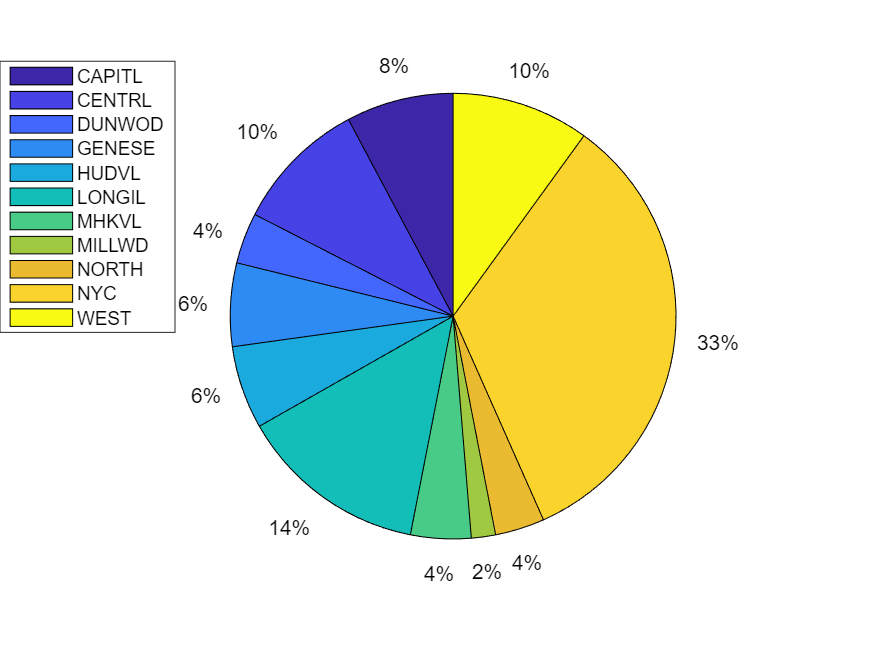

pie([mean_CAPITL, mean_CENTRL, mean_DUNWOD, mean_GENESE, mean_HUDVL, mean_LONGIL, mean_MHK_VL, mean_MILLWD, mean_NORTH, mean_NYC, mean_WEST])
legend("CAPITL","CENTRL","DUNWOD", "GENESE","HUDVL", "LONGIL", "MHKVL", "MILLWD", "NORTH", "NYC","WEST")

legend("Position",[0,0.5,0.2,0.4])